# Taller III

### 06/04/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 1 y 2*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- No olvidar el criterio de parada de ErrorRelativo, ya que en general este error converge primero que el Error Absoluto, y esto detiene el metodo antes de un delta deseado, si el método se encuentra programado de esta manera es importante no modificar este criterio, y de igual manera esto se verá reflejado en el criterio $\textrm{Err}$ que nos retorna el método.

- Importante, pero esto es más un recordatorio. Matlab es además de un software un lenguaje, así podemos tareas repetitivas volverlas métodos iterativos, eso es lo que se les propone con el método **Jac_GS**, invitarlos a que exploren la posibilidad y realicen métodos que les haga la vida más fácil.

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

*Notas frente al uso de los métodos:*

#### *        Métodos de una variable*

`    [c, err, n] = bisect(Function, Num1, Num2, Tol), `Método de bisección.

            - Function funcion definida @

            - Num1 y Num2 son los extremos del intervalo

            - Tol Es la tolerancia definida a la iteración

            - c es la aproximación obtenida por el método

            - err Error asociado a la iteración

            - n Pasos realizados para alcanzar la tolerancia

`    [p, k, err, P] = fixpt(g, p0, tol, max1), `Método de punto fijo.

            - g funcion creada con @

            - p0 es el supuesto inicial para el punto fijo

            - tol es la tolerancia

            - max1 es el numero maximo de iteraciones

            - p es la aproximacion del punto fijo

            - k es el numero de iteraciones realizadas

            - err es el error en la aproximacion

            - P' contiene la secuencia {pn}

`    [p, err, k, yc] = newton(f, df, p0, delta, epsilon, max1), `Método de Newton.

            - f funcion creada con @

            - df funcion derivada creada con @

            - p0 es la aproximacion inicial a cero de  f

            - delta es la tolerancia para  p0

            - epsilon es la tolerancia para los valores de la funcion  y

            - max1 es el numero maximo de iteraciones

            - p0 es la aproximacion de Newton-Raphson hacia cero

            - err es el error estimado para  p0

            - k es el numero de iteraciones

            - y es el valor de la funcion  f(p0)

`    [p, err, k, yc] = newton(f, df, d2f, p0, delta, epsilon, max1), `Método de Newton modificado.

            - f funcion creada con @

            - df primera derivada, funcion creada con @

            - d2f segunda derivada, funcion creada con @

            - p0 es la aproximacion inicial a cero de  f

            - delta es la tolerancia para  p0

            - epsilon es la tolerancia para los valores de la funcion  y

            - max1 es el numero maximo de iteraciones

            - p0 es la aproximacion de Newton-Raphson hacia cero

            - err es el error estimado para  p0

            - k es el numero de iteraciones

            - y es el valor de la funcion  f(p0)

*Frente a la definición del método de Newton acelerado, recordemos que este puede ser invocado usando el método de Newton y agrendando la multiplicidad de la raiz a hallar en la definición de la función o en la definición de la derivada de la función, tal como se indica:*

$x_{k+1} =x_k -M\frac{\;f\left(x_k \right)}{f^{\prime } \left(x_k \right)}$ : Definimos entonces $f\left(x_k \right):=M\;f\left(x\right)\;|\;f^{\prime } \left(x_k \right):=\frac{f^{\prime } \left(x\right)}{M}$.

#### *        Métodos de sistemas de ecuaciones*

`    X = jacobi(A, B, P, delta, max1), `Método de Jacobi.

            - A es una matriz no singular  N x N

            - B es una matriz  N x 1

            - P es una matriz  N x 1; los supuestos iniciales

            - delta es la tolerancia para  P

            - max1 es el numero maximo de iteraciones

            - X es una matriz  N x 1: la aproximacion de jacobi a

                la solucion de  AX = B

`    X = gseid(A, B, P, delta, max1), `Método de Gauss - Seidel.

            - A es una matriz no singular  N x N

            - B es una matriz  N x 1

            - P es una matriz  N x 1; el supuesto inicial

            - delta es la tolerancia para  P

            - max1 es el numero maximo de iteraciones

            - X es una matriz  N x 1: la aproximacion de gauss-seidel a

                la solucion de  AX = B

`    Y = sor(A, B, P, w, delta, max1), `Método de SOR

            - A es una matriz no singular  N x N

            - B es una matriz  N x 1

            - P es una matriz  N x 1; el supuesto inicial

            - w parametro de sobrerelajacion (0<w<2)

            - delta es la tolerancia para  P

            - max1 es el numero maximo de iteraciones

             - Y es una matriz  N x 1: la aproximacion de SOR a

                la solucion de  AX = B

`    P = newdim (F, JF, P, delta, epsilon, max1), `Método de Newton

            - F funcion del sistema creada con @

            - JF matriz jacobiana, funcion creada con @

            - P es la aproximacion inicial a la solucion

            - delta es la tolerancia para  P

            - epsilon es la tolerancia para  F(P)

            - max1 es el numero maximo de iteraciones

            - P es la aproximacion a la solucion

            - iter es el numero de iteraciones realizadas

            - err es el error estimado para  P

Recordar documentarse en cada una de las rutinas disponibles del curso y de MATLAB para afrontar distintas situaciones, MATLAB es su aliado.

#### Sistemas de ecuaciones no lineales

Para el taller de esta semana se solucionan los ejercicios del taller 4 $6,7$ se propone el uso de Newtondim y las propias herramientas de Matlab

**6) **Considere el sistema $\mathit{\mathbf{F}}\left(\mathit{\mathbf{x}}\right)=0$, donde:


$$\mathit{\mathbf{F}}\left(\mathit{\mathbf{x}}\right)=\left\lbrack \begin{array}{c}
4\;x_1^{\;3} -27\;x_1 \;x_{2\;}^{\;2} +25\\
4\;x_1^{\;2} -3x_2^{\;3} -1
\end{array}\right\rbrack$$


Utilice el método de Newton para aproximar el único punto de intersección ente las curvas

clear
syms F(x, y)

F(x, y) = [4*x^3 - 27*x*y^2 + 25, 4*x^2 - 3*y^3 - 1]' % Definimos una función de 2 variables

$$F(x, y) = \left(\begin{array}{c} 4\,x^{3}-27\,x\,y^{2}+25\\ 4\,x^{2}-3\,y^{3}-1 \end{array}\right)$$

F1 = 4*x^3 - 27*x*y^2 + 25; % Definimos por componentes para graficar
F2 = 4*x^2 - 3*y^3 - 1; % Definimos por componentes para graficar

x0 =      1
     1


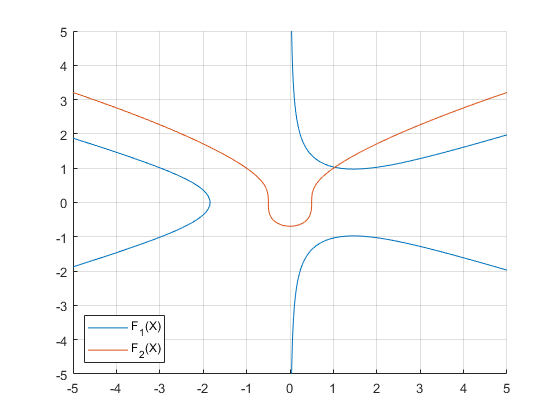


clf('reset')
hold on
fimplicit(F1) % Gráficamos la primera componente
fimplicit(F2) % Gráficamos la segunda componente
legend('F_1(X)','F_2(X)', 'Location', 'southwest') % Generamos una legenda y la relocalizamos
grid on
hold off

JF = jacobian(F, [x, y]) % Definimos el Jacobiano de la función

$$JF(x, y) = \left(\begin{array}{cc} 12\,x^{2}-27\,y^{2} & -54\,x\,y\\ 8\,x & -9\,y^{2} \end{array}\right)$$

F = matlabFunction(F) % Procesamos las funciones

F = function_handle with value:
    @(x,y)[x.*y.^2.*-2.7e+1+x.^3.*4.0+2.5e+1;x.^2.*4.0-y.^3.*3.0-1.0]


JF = matlabFunction(JF); % Procesamos las funciones

F = @(X) F(X(1), X(2)) % Procesamos las funciones

F = function_handle with value:
    @(X)F(X(1),X(2))


JF = @(X) JF(X(1), X(2)); % Procesamos las funciones

Notemos que realizamos la conversión de función mátematica y luego de multivariable a vectorial, esta es la metodología clave a seguir para definir las funciones para el método

x0 = ones([2, 1]) % Defino mi aproximación inicial

err = 7.4496e-07

relerr = 5.1179e-07

iter = 3

X =     1.0311
    1.0274


X = newdim(F, JF, x0, 1E-10, 1E-10, 100) % Aplico el método

Importante, revisar como el método recibe sus argumentos y los trabaja, es primordial entender como entregar los argumentos y como procesar la función antes de iterar.

**7) **Considere el sistema $\mathit{\mathbf{F}}\left(\mathit{\mathbf{x}}\right)=0$, donde:


$$\mathit{\mathbf{F}}\left(\mathit{\mathbf{x}}\right)=\left\lbrack \begin{array}{c}
x_1^{\;2} +x_1 \;x_2 \;x_3 +x_3^{\;3} \\
x_1^{\;3} \;x_2 +x_2 \;x_3^{\;2} \\
x_1 \;/\;x_2^{\;3} 
\end{array}\right\rbrack$$


Utilice el método de Newton para encontrar una solución de este sistema. Como primera aproximación use ones(1,3). 

clear
syms F(x, y, z)

F(x, y, z) = [x^2 + x*y*z + z^3; y*x^3 + y*z^3; x / y^3] % Definimos la función

$$F(x, y, z) = \left(\begin{array}{c} x^{2}+y\,x\,z+z^{3}\\ y\,x^{3}+y\,z^{3}\\ \frac{x}{y^{3}} \end{array}\right)$$

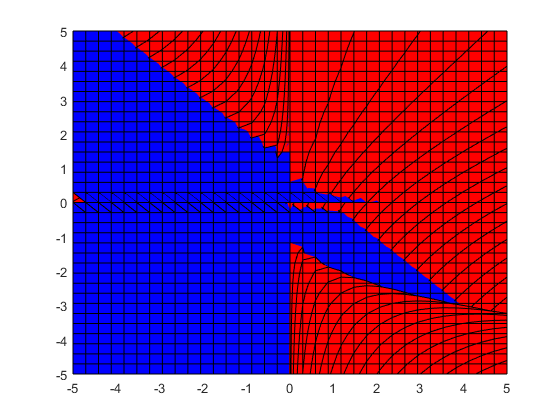

F1 = x^2 + x*y*z + z^3; % Definimos por componentes para graficar
F2 = y*x^3 + y*z^3; % Definimos por componentes para graficar
F3 = x / y^3; % Definimos por componentes para graficar

clf('reset')
hold on
fimplicit3(F1, 'r') % Gráficamos la primera componente
fimplicit3(F2, 'b') % Gráficamos la segunda componente
fimplicit3(F3, 'g') % Gráficamos la tercera componente
hold off

Veamos que obtuvimos una gráfica bastante complicada de entender, incluso si la rotamos y encontramos sus elementos, es fácil ver que tiene comportamientos bastante impredecibles, por lo que podemos ver que al tratarse de funciones de más de 2 variables, los problemas se vuelven abstractos y dificiles de entender, por esto nos entregan una estimación inicial a trabajar

x0 = ones([3, 1]); % Defino mi estimación

JF = jacobian(F, [x, y, z]); % Hallamos el resto de componentes

F = matlabFunction(F); % Procesamos los componentes
JF = matlabFunction(JF); % Procesamos los componentes

F = @(X) F(X(1), X(2), X(3)); % Vectorizamos la función
JF = @(X) JF(X(1), X(2), X(3)); % Vectorizamos la función

X = newdim(F, JF, x0, 1E-10, 1E-10, 100)

err = 11.9126

relerr = 0.1667

iter = 23

X =     0.0000
   71.4756
   -0.0000


#### Sobre Newtondim

*Ya que estuvimos trabajando hoy el método se propone la revisión del ejercicio de repaso para esta semana, el cual indica*

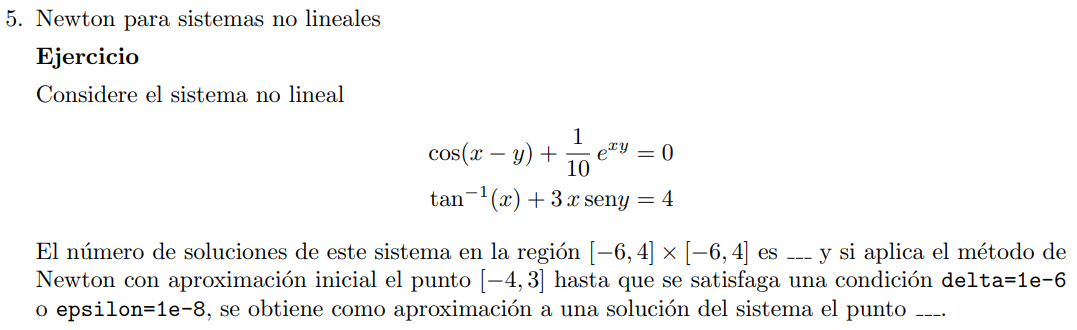

Ya este proceso se convierte en homologo, y veamos que ya es similar la metodología a seguir para resolver estos problemas, así

clear
syms F(x, y)

Defino los componentes, función y Jacobiano

F(x, y) = [cos(x - y) + 1/10*exp(x*y);  atan(x) + 3*x*sin(y) - 4];
JF(x, y) = jacobian(F, [x, y]);

Defino los elementos necesarios para gráficar

F1 = cos(x - y) + 1/10*exp(x*y);
F2 = atan(x) + 3*x*sin(y) - 4;

Procedemos a graficar

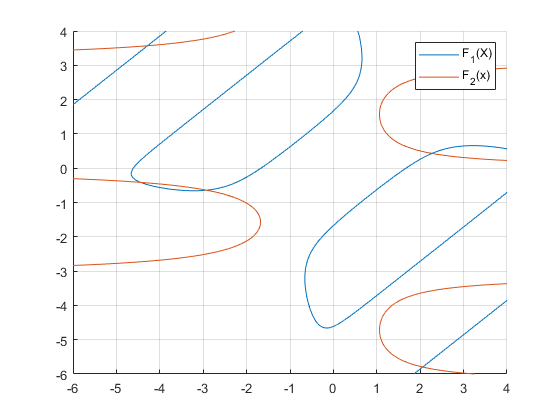

clf('reset')
hold on
fimplicit(F1, [-6 4 -6 4])
fimplicit(F2, [-6 4 -6 4])
legend('F_1(X)', 'F_2(x)')
grid on
hold off

*Tenemos 5 soluciones en el intervalo*

Definimos el resto de componentes para la iteración

x0 = [-4 3]';

Procesamos los componentes

F = matlabFunction(F);
JF = matlabFunction(JF);

Vectorizamos nuestros componentes

F = @(X) F(X(1), X(2));
JF = @(X) JF(X(1), X(2));

Aplicamos el método

X = newdim(F, JF, x0, 1E-6, 1E-8, 100)

err = 1.8447e-05

relerr = 3.3081e-06

iter = 4

X =    -4.2837
    3.5702
